# **Welcome to Deci**

**A fluid pipeline to analyze EEG Data with ease**

Written and Compiled by @John Nguyen of Robert Reinhart Lab on 10/15/2018, contact: Akida@bu.edu

## 0. MainMenu

Deci = [];
Deci.File = mfilename;
Deci.Folder.Raw         = ['C:\Users\User\Desktop\Test\GM_Data'];                               
Deci.SubjectList        = 'all';
Deci.Step               =1; % Define Trial;
Deci.Proceed            =1;                          % If 0 or 1, Do you want Deci to automatically proceed to next steps? Suggest 0 for first-time users.
Deci.Layout.Noeye       = 'easycap_rob_noeye.mat';         % Layout without Ocular Channels, Default is ReinhartLab 1020 system
Deci.Layout.eye         = 'easycap_rob_binocular.mat';           % Layout with Ocular Channels
Deci.PCom               = 0;        % Activates Parallel Computing (if availible)
Deci.Debug              = 0;        % Activates dbstop if error
Deci.Folder.Version     = ['C:\Users\User\Desktop\Test\GM_Processed'];     

Deci = Checkor(Deci);

## 1. Trial Definitions

    Deci.DT.Type = 'Manual';             
    Deci.DT.Starts     = {17};         %Cell Array of Markers for ETs Start.
    Deci.DT.Ends       = {18};         %Cell Array of Markers for ETs End.
    Deci.DT.Markers    = {[12 30 37 31 13 20 23 21 18] [12 30 37 34 13 20 22 21 18] [12 30 38 31 13 20 23 21 18] [12 30 38 34 13 20 22 21 18]};   
    Deci.DT.Locks      = [30 30 30 30];     
    Deci.DT.Conditions = [1 2 1 2];         
    Deci.DT.Toi        = [-2 2]; 

if Deci.Step <= 1
    DefineTrialor(Deci);
    if ~Deci.Proceed; return; end
end

evaluating trialfunction 'expfunor'
found 0 events
created 40 trials
the call to "ft_definetrial" took 1 seconds


## 2. PreProcessing Steps

####    Rereference channel to average of Implicit Electrode and Offline Reference

   Deci.PP.Imp                = 'TP10:TP9'; % 'Impicit Reference?[Implicit:RefChannels without Implicit]'
   Deci.PP.Ocu                = 'TVEOG:BVEOG,LHEOG:RHEOG';    % 'Ocular Reref?[Ref-Channels without Ref]'

#### Other Processing Steps

    Deci.PP.ScalingFactor       = [];               % Scalar, If the data needs to scale
    Deci.PP.HBP                 = [];               % Scalar,High-bandpass filter, in Hz.
    Deci.PP.Demean              = [-.5 -.2];        % [Beg End], Secs Relative to .DT.Locks, Baseline Window for Correction.
    
    Deci.PP.Repair              = [];                           % Structure, View and Repair (via interpoltation) Channels
%     Deci.PP.Repair.Type         = 'Manual';                   % String,'Manual' or 'Auto'
%     Deci.PP.Repair.Auto         = {};                         % Nx1 Subject cell array of Mx1 cells of M Channels to reject.

    Deci.PP.CleanLabels = 0; % Binary, normalize electrode names to be compatiable with Reinhart Lab's Needs.

if Deci.Step <= 2
    PreProcessor(Deci)
    if ~Deci.Proceed; return; end
end

processing channel { 'TVEOG' 'Fz' 'F3' 'F7' 'LHEOG' 'FC5' 'FC1' 'C3' 'T7' 'TP9' 'CP5' 'CP1' 'Pz' 'P3' 'P7' 'O1' 'Oz' 'O2' 'P4' 'P8' 'CP6' 'CP2' 'Cz' 'C4' 'T8' 'RHEOG' 'FC6' 'FC2' 'F4' 'F8' 'BVEOG' 'AF7' 'AF3' 'AFz' 'F1' 'F5' 'FT7' 'FC3' 'C1' 'C5' 'TP7' 'CP3' 'P1' 'P5' 'PO7' 'PO3' 'POz' 'PO4' 'PO8' 'P6' 'P2' 'CPz' 'CP4' 'TP8' 'C6' 'C2' 'FC4' 'FT8' 'F6' 'AF8' 'AF4' 'F2' 'FCz' }
reading and preprocessing
reading and preprocessing trial 40 from 40

the call to "ft_preprocessing" took 0 seconds


preprocessing
preprocessing trial 40 from 40

the call to "ft_preprocessing" took 0 seconds
preprocessing
preprocessing trial 40 from 40

the call to "ft_preprocessing" took 0 seconds
preprocessing
preprocessing trial 40 from 40

the call to "ft_preprocessing" took 0 seconds
preprocessing
preprocessing trial 40 from 40

the call to "ft_preprocessing" took 0 seconds
preprocessing
preprocessing trial 40 from 40

the call to "ft_preprocessing" took 0 seconds
input dataset 1, 60 channels, 40 trials
input dataset 2, 1 channels, 40 trials
input dataset 3, 1 channels, 40 trials
concatenating the channels within each trial
preprocessing
preprocessing trial 40 from 40

the call to "ft_preprocessing" took 0 seconds


## 3. Artifact Rejection

#### Individual Component Analysis

    Deci.Art.ICA.Reject                     = 0; % Whether or Not to do ICA
    Deci.Art.ICA.Eye.Chans           = {'BVEOG','RHEOG','AF7','AF8'}; 

#### Trial Artifacts

     Deci.Art.TR.Toi              = [-.5 -.2];          % Time Range of Interest to look for Artifacts
     Deci.Art.TR.rToi           = [-.5 1];              % Only available for Shifts.
 
     Deci.Art.TR.Eye                  = [];               % Comment the rest of .Eye to not do Eye Artifact Trial Rejection
%      Deci.Art.TR.Eye.Interactive      =  0;                % Enable Interactive Trial Artifact Rejection
%      Deci.Art.TR.Eye.Chans            = {'BVEOG','RHEOG','AF7','AF8'};    % 1xChan Cell Array of Ocular Eye Channels

    Deci.Art.TR.Muscle               = [];               % Comment the rest of .Muscle to not do Muscle Artifact Trial Rejection
%     Deci.Art.TR.Muscle.Interactive   = 0;                % Enable Interactive Trial Artifact Rejection

#### Manual Visual Artifact Rejection

    Deci.Art.Manual = [];
%     Deci.Art.Manual.Toi              = [-.5 -.2];
%     Deci.Art.Manual.rToi              =[-.5 1];  % Only available for Shifts.

if Deci.Step <= 3
    Artifactor(Deci);
    if ~Deci.Proceed; return; end
end

## 4. Analysis

#### General Set-Up

    Deci.Analysis.ArtifactReject     =0;                    % Specify whether or not to Apply Trial Rejection
    Deci.Analysis.Channels           = {'Fz','Cz','C3','O1'};                % Cell array of channels or 'all'
    Deci.Analysis.Laplace            =0;                   % Leave .Laplace as 0 to not do a Laplacian Transformation based on file realistic_1005.txt format
    
    Deci.Analysis.Redefine = [];                             % Only available for Shifts.
%     Deci.Analysis.Redefine.Bsl = [-.5 -.2];
%     Deci.Analysis.Redefine.ERPToi = -.5;
    

#### Time-Frequency Analysis

    Deci.Analysis.Freq               = [];           % Comment the rest of .Freq to not do Fourier Transformation
    Deci.Analysis.Freq.method        = 'wavelet';    % Currently only uses Wavelet Decomp
    Deci.Analysis.Freq.foi           = exp(linspace(log(2),log(40),40));       % Frequency of Interest
    Deci.Analysis.Freq.width         = 7 ;           % Width
    Deci.Analysis.Freq.gwidth        = 4;            % Gwidth
    Deci.Analysis.Freq.Toi           = [-.5 1];       % Time Range
    
    Deci.Analysis.Freq.Redefine = 0;   % 1 for Both BSL and Freq, or 2 just BSL % Only available for Shifts.

#### Event Related Potential Analysis

  Note that entire Time Range will be analyzed.

    Deci.Analysis.ERP                =  0;

#### Cross-Frequency Coupling 

            Requires* .Freq * to have been done.

    Deci.Analysis.Freq.CFC = [];
    Deci.Analysis.Freq.CFC.chanlow = {'Fz' 'Cz'};
    Deci.Analysis.Freq.CFC.chanhigh = {'C3' 'O1'}; %Try not to do all to all if you have more than 10 chans
    
    Deci.Analysis.Freq.CFC.latencyhigh = [-.5 .5]; %no implementation yet to check for edge artifactsm so be careful
    Deci.Analysis.Freq.CFC.latencylow = [-.5 .5];
    
    Deci.Analysis.Freq.CFC.Freqhigh = 'beta';
    Deci.Analysis.Freq.CFC.Freqlow = 'theta';
    
    Deci.Analysis.Freq.CFC.timebin = 5;
    Deci.Analysis.Freq.CFC.methods = {'mi','plv'};  % can only currently handle 'plv' or 'mi'(pac)
    Deci.Analysis.Freq.CFC.keeptrials =  'no';
        
    %     cfg.method     = string, can be
    %                     'coh' - coherence [Fourier-Fourier]
    %                     'plv' - phase locking value [phase-phase of amp]
    %                     'mvl' - mean vector length [phase-amp]
    %                     'mi'  - modulation index  [phase-amp]
    %                     'cs_cc'  - circstats circular-circular [phase-phase]
    %                     'cs_cl'  - circstats circular-linear [phase-amp]

####  Not Available

    Deci.Analysis.EvokedPower        = 0; %Not Available

if Deci.Step <= 4
    Analyzor(Deci)
    if ~Deci.Proceed; return; end
end

the input is raw data with 62 channels and 40 trials
averaging trials
averaging trial 20 of 20

the call to "ft_timelockanalysis" took 0 seconds
the input is raw data with 62 channels and 40 trials
processing trials
trial 20, frequency 39 (39.99 Hz)

the call to "ft_freqanalysis" took 2 seconds
the input is freq data with 2 channels, 10 frequencybins and 1001 timebins
the input is freq data with 2 channels, 12 frequencybins and 1001 timebins
the input is freq data with 2 channels, 10 frequencybins and 1001 timebins
the input is freq data with 2 channels, 12 frequencybins and 1001 timebins
the input is raw data with 62 channels and 40 trials
averaging trials
averaging trial 20 of 20

the call to "ft_timelockanalysis" took 0 seconds
the input is raw data with 62 channels and 40 trials
processing trials
trial 20, frequency 39 (39.99 Hz)

the call to "ft_freqanalysis" took 2 seconds
the input is freq data with 2 channels, 10 frequencybins and 1001 timebins
the input is freq data with 2 cha

## 5. Plotting

#### General Set-Up

    Deci.Plot.GA =  0;                       % 0 for Individual Plots, 1 for GrandAverage
    Deci.Plot.Scale = 'linear';
    Deci.Plot.Save = [];
    Deci.Plot.Save.Format =  'fig';

#### Math

    Deci.Plot.Math = [];
%   Deci.Plot.Math.Form = {'[x1+x3]','[x2+x4]','x6-x5'};    % in this example sum of Cond1 and Cond3 makes Cond 5,                
    Deci.Plot.Math.Type = 0;                    % 0 = no math plots, 1 = only math plots, 2 = both math and single plots
    

#### Time-Frequency

    Deci.Plot.Freq = [];
    
    
    Deci.Plot.Freq.Plot = 1;                % 1 or 0 to do Freq Plots
    Deci.Plot.Freq.Foi = [4 8]; 
    Deci.Plot.Toi = [];
    Deci.Plot.Freq.Channel = [{'VEM'  'HEM'  'F3'  'F4'  'C3'  'C4'  'P3'  'P4'  'PO3'  'PO4'  'O1'  'O2'  'OL'  'OR'  'T3'  'T4' 'T5'  'T6'  'Fz'  'Cz'  'Pz'  'LM' 'RM'}];   
    Deci.Plot.Freq.Type = 'TotalPower';     % Use 'TotalPower','ITPC' or 'EvokedPower'
     
    Deci.Plot.Freq.Bsl = [-.5 -.2];           % Baseline Correction Time
    Deci.Plot.Freq.Roi = [];          % use 'maxmin','maxabs or [min max] to set.
    Deci.Plot.Freq.BslType ='db';    % Use 'absolute','relative','relchange','db','normchange'

    Deci.Plot.Freq.Topo = 1;
    Deci.Plot.Freq.Square = 1;
    

####   Time-Frequency Wires

    Deci.Plot.Freq.Wires = [];
%         Deci.Plot.Freq.Wires.Collapse = 'Time';        %Which Dim to Collapse 'Time' or 'Freq'
%         Deci.Plot.Freq.Wires.avgoverfreq = 'no';
%         Deci.Plot.Freq.Wires.avgovertime= 'yes';
%         Deci.Plot.Freq.Wires.frequency = [4 8];
%         Deci.Plot.Freq.Wires.latency = [.1  .5];
%         Deci.Plot.Freq.Wires.nanmean = 'no';
    

####   ERP

    Deci.Plot.ERP = []; %Not Available to plot
    %     Deci.Plot.ERP.Channel = 'all';              % Cell array of channels or 'all'

####   PRP

    
    Deci.Plot.PRP = [];                     %Requires .Freq/.ERP to be filled out
    %Power related Potential
    %Plot 1 = Collapsed-Frequency/Channel Freq.Type Data
    %plot 2 = Collapsed-Channel           ERP Data
    %plot 3 = Condition-Specific Timepoint by Timepoint Freq-ERP coorelation across subjects
    %plot 4 = Collapsed-Time/Freq/Channel Condition-Specific Subject by Subject plotted along Freq-YAxis, ERP-XAxis
    %Changes .GA into 0
    %     Deci.Plot.PRP.label = 1;                %Whether or Not to add subject info on plot 4
    %     Deci.Plot.PRP.ScatterToi = [.3 .7];     %Time range for plot 4
    

####     Cross-Frequency Coupling

    Deci.Plot.CFC = []; 
    Deci.Plot.CFC.method = 'plv';
    Deci.Plot.CFC.Topo = 1;
    Deci.Plot.CFC.Square = 1;
    Deci.Plot.CFC.Hist = 1;
    Deci.Plot.CFC.Roi = 'maxmin';          % Power Range of Interest
    

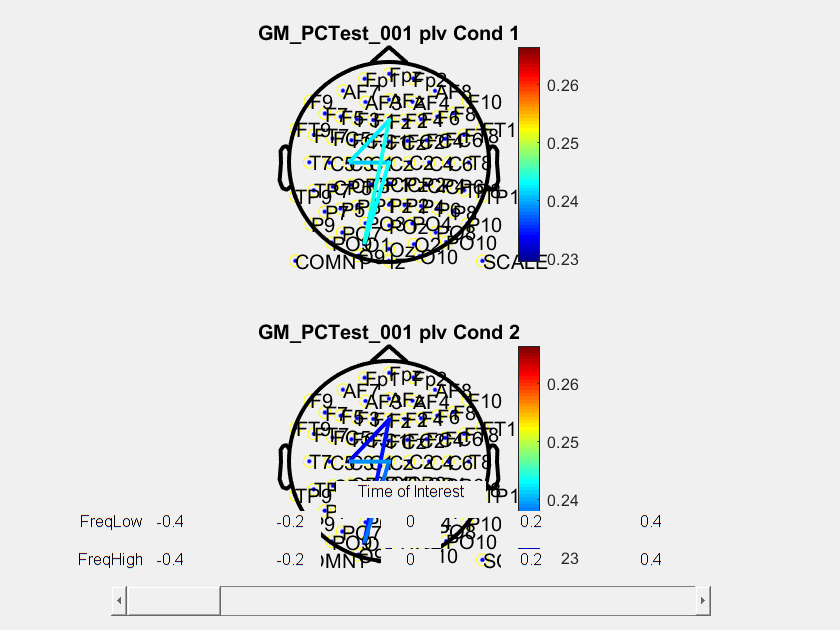

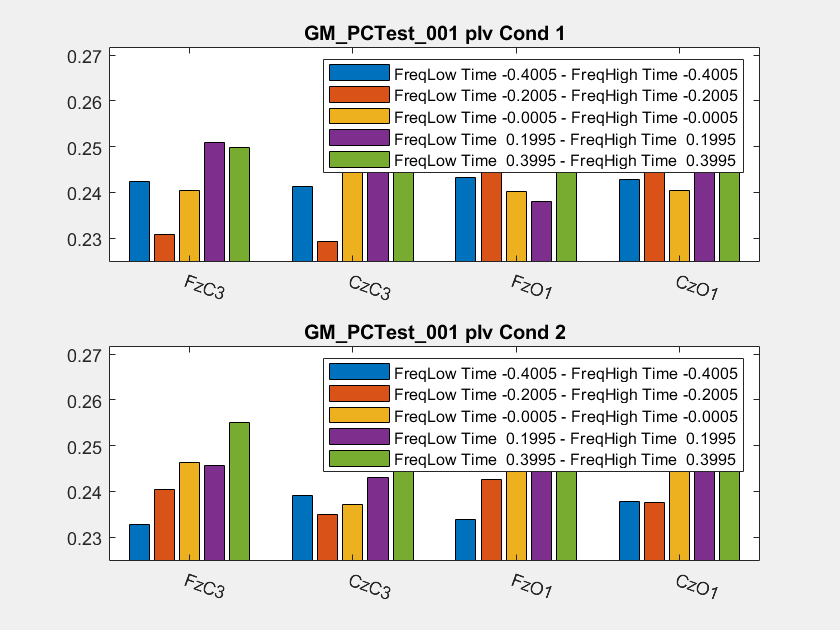

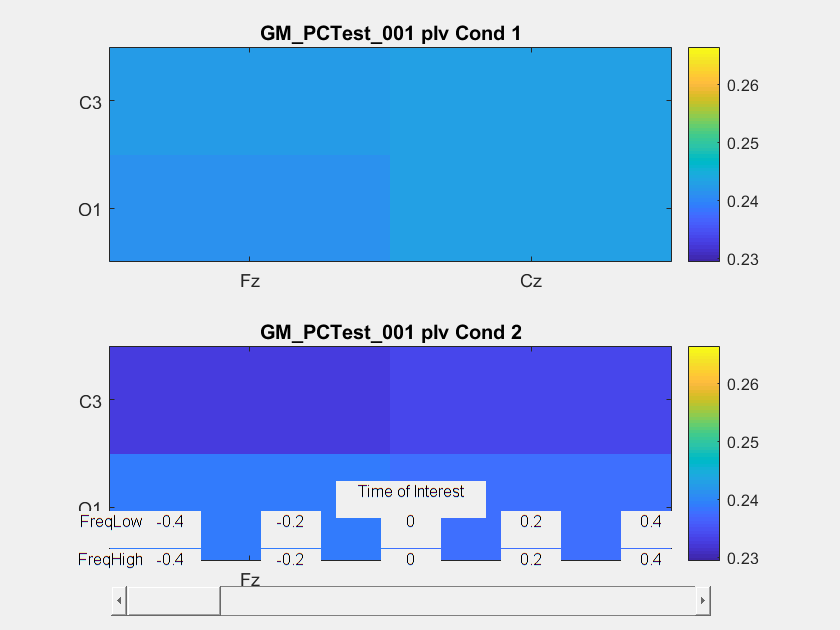

reading layout from file easycap_rob_noeye.mat
the call to "ft_prepare_layout" took 0 seconds


plotting connections...
plotting connection 3 from 4 (Fz -> O1)

the call to "ft_topoplotCC" took 0 seconds
reading layout from file easycap_rob_noeye.mat
the call to "ft_prepare_layout" took 0 seconds


plotting connections...
plotting connection 2 from 4 (Cz -> C3)

the call to "ft_topoplotCC" took 0 seconds


if Deci.Step <= 5
    Plottor(Deci);
    if ~Deci.Proceed; return; end
end